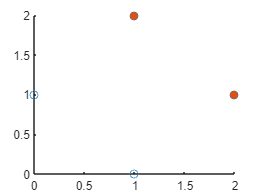

%a
q4.smat=[0 1; 1 2; 2 1; 1 0];
q4.tmat=[0 1 1 0]';

h1 = [0 1 1 1]';
h2 = [0 1 1 0]';

figure 
hold on
scatter(q4.smat(:,1),q4.smat(:,2))
scatter(q4.smat(2:3,1),q4.smat(2:3,2),'filled') 


%b
w11 = 1;
w21 = 0;
b1 = -0.5;
w12 = 1;
w22 = 1;
b2 = -1.5;
% test
(w11 * q4.smat(:,1) + w21 * q4.smat(:,2) + b1) >= 0

ans = 4×1 logical array
   0
   1
   1
   1


(w12 * q4.smat(:,1) + w22 * q4.smat(:,2) + b2) >= 0

ans = 4×1 logical array
   0
   1
   1
   0



wih=[w11 w21; w12 w22]

wih =      1     0
     1     1


hbias = [b1 b2]

hbias =          -0.5         -1.5



%c
whout1 = -1;
whout2 = 2;
bhout = -0.5;
(whout1 * h1 + whout2 * h2 + bhout) >= 0

ans = 4×1 logical array
   0
   1
   1
   0



whout = [whout1 whout2]

whout =     -1     2


obias = bhout

obias =          -0.5


%d
%{
q4net0.wih = wih;
q4net0.hbias = hbias;
q4net0.whout = whout;
q4net0.obias = obias;
%}
q4net0 = initnet3(2,2,1,2,2,0);

q4net1k=bp3(q4net0,q4,10000,1,0,0);
q4net1k.wih

ans =        1.2432      0.50591
       2.9167        3.137


q4act1k=forw3(q4net1k,q4)

q4act1k = struct with fields:
    stim: [4×2 double]
     hid: [4×2 double]
     out: [4×1 double]

q4act1k.hid

ans =      -0.16336     -0.85915
       0.6105      0.93985
      0.79259      0.92557
      0.20103     -0.88541


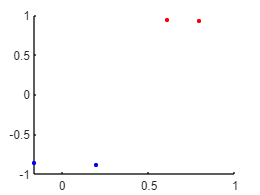

color=[q4.tmat,zeros(size(q4.tmat)),1-q4.tmat];
figure 
scatter(q4act1k.hid(:,1),q4act1k.hid(:,2),10,color,"filled")